data=dlmread('Bandgap.csv',',',1,0);
temp=data(:,2)*100+273;
l=.020;
l_err=.0001;
w=.010;
w_err=.0001;
t=.001;
t_err=.0001;
I=data(:,4)

I =     0.0020
    0.0020
    0.0021
    0.0022
    0.0023
    0.0025
    0.0027
    0.0028
    0.0028
    0.0030


I_err=.00001

I_err = 1.0000e-05

V=data(:,1)

V =     1.3790
    1.3660
    1.2990
    1.2660
    1.1750
    1.0190
    0.8970
    0.8270
    0.7960
    0.6830


V_err=.001

V_err = 1.0000e-03

k=1.381*10^(-23);
x=(2*k.*temp).^-1;
con=l*data(:,4)./(data(:,1)*w*t)

con =     2.8426
    2.9429
    3.2333
    3.3965
    3.8638
    4.8871
    5.9532
    6.7231
    7.1106
    8.7555


con_err=((l_err.*I./(V*w*t)).^2+(l*I_err./(V*w*t)).^2+(l.*I*V_err./(w*t.*V.^2)).^2 ...
    +(l.*I*w_err./(w^2*t.*V)).^2+(l.*I*t_err./(w.*V*t)).^2).^.5

con_err =     0.0350
    0.0361
    0.0394
    0.0412
    0.0465
    0.0583
    0.0705
    0.0794
    0.0839
    0.1030


log_con_err=con_err./con

log_con_err =     0.0123
    0.0123
    0.0122
    0.0121
    0.0120
    0.0119
    0.0118
    0.0118
    0.0118
    0.0118


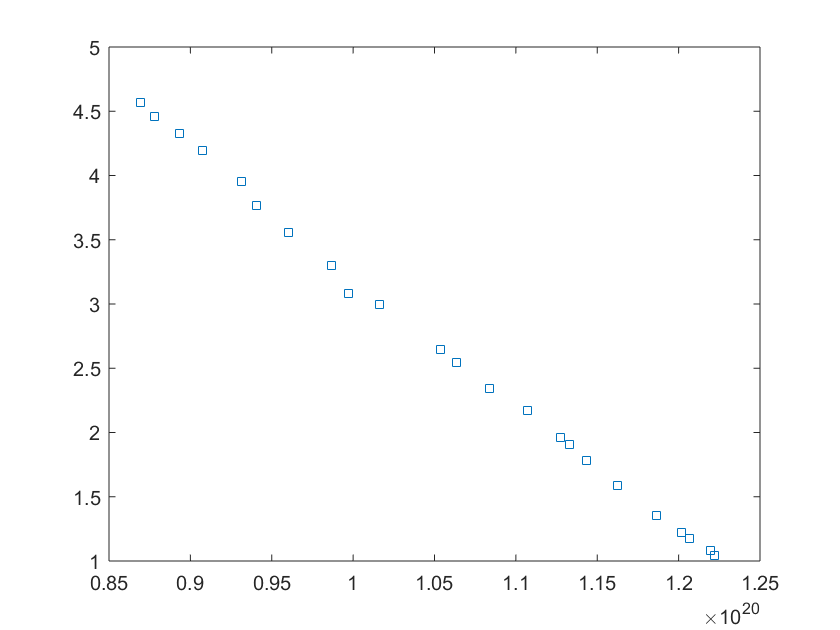

plot(x,log(con),'s')

fit=myfit(x,log(con),log_con_err)

fit =    13.0823   -0.0000
    0.0255    0.0000


E_gap=-fit(1,2)./(1.6*10^-19)

E_gap = 0.6175

E_gap_err=fit(2,2)/(2.6*10^-19)

E_gap_err = 9.1176e-04

function rval = myfit(x,y,ey)
    sx = sum(x ./ (ey .^ 2) );
    sy = sum(y ./ (ey .^ 2) );
    sxx = sum((x .* x) ./ (ey .^ 2) );
    sxy = sum((x .* y) ./ (ey .^ 2) );
    s = sum(1 ./ (ey .^ 2) );
    delta=sxx*s-sx*sx;
    a=(sxx*sy-sx*sxy)/delta;
    ea=sqrt(sxx/delta);
    b=(s*sxy-sx*sy)/delta;
    eb=sqrt(s/delta);
    rval=[ a, b ; ea, eb ];
end